clc,clear
CSI4=load("CSI4.mat","CSI_LTF1");
CSI4=CSI4.CSI_LTF1;

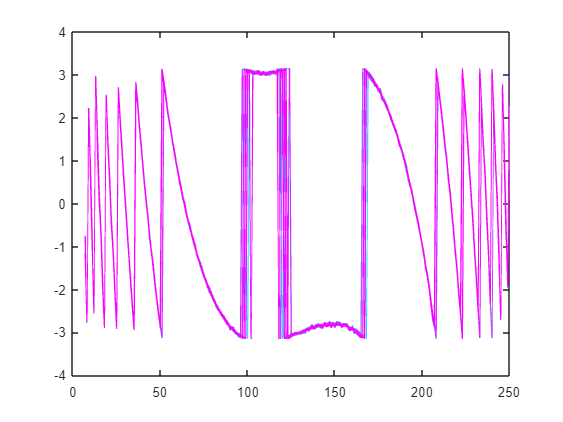

mod_Z=abs(CSI4);
phase_Z=angle(CSI4);

matrixA=(7:127);matrixB=(131:250);
matrix=[matrixA,matrixB];

matrix1=matrix-ones([1,241]);

removeCols = [1:6, 128:130,251:256];
% 保留的列的索引
keepCols = setdiff(1:size(phase_Z, 2), removeCols);
% 删除指定的列
newphase_Z = phase_Z(:, keepCols);
% 保留的列的索引
keepCols = setdiff(1:size(phase_Z, 2), removeCols);
% 删除指定的列
newmod_Z = mod_Z(:, keepCols);
CSI4_new=CSI4(:,keepCols);

c=cool(24);
for i = 1:24
figure(1);
plot(matrix,newphase_Z(i,:),'color', c(i,:),'DisplayName',strcat('第',num2str(i),'条天线'),'Linewidth',1);
hold on;
end

% 初始化解卷绕后的CSI数据矩阵
unwrappedCSI = zeros(size(newphase_Z));

% 初始化phasediff矩阵
phasediff = zeros(size(newphase_Z));

% 先进行时间域上的解卷绕
for f = 1:241
    for t = 2:24
        % 计算相邻时刻的相位差
        phase_diff = newphase_Z(t, f) - newphase_Z(t-1, f);
        
        % 如果相位差超过pi，进行解卷绕
        if abs(phase_diff) > pi
            if phase_diff > 0
                newphase_Z(t, f) = newphase_Z(t, f) - 2 * pi;
            else
                newphase_Z(t, f) = newphase_Z(t, f) + 2 * pi;
            end
        end
    end
end

for f = 1:241
    for t = 2:24
        % 计算相邻时刻的相位差
        phase_diff = newphase_Z(t, f) - newphase_Z(t-1, f);
        
        % 将相位差存储到phasediff矩阵中
        phasediff(t, f) = phase_diff;
    end
end

% 查找 phasediff 矩阵中大于 pi 的值的索引
[rows, cols] = find(abs(phasediff) > pi);

% 如果找到大于 2pi 的值，打印这些值及其索引
if ~isempty(rows)
    fprintf('在 phasediff 矩阵中找到大于 pi 的值:\n');
    for i = 1:length(rows)
        fprintf('值: %f, 位置: (%d, %d)\n', phasediff(rows(i), cols(i)), rows(i), cols(i));
    end
else
    disp('phasediff 矩阵中没有大于 pi 的值。');
end

phasediff 矩阵中没有大于 pi 的值。



% % 输出 phasediff 矩阵用于检查
% disp('Phasediff 矩阵为:');
% disp(phasediff);



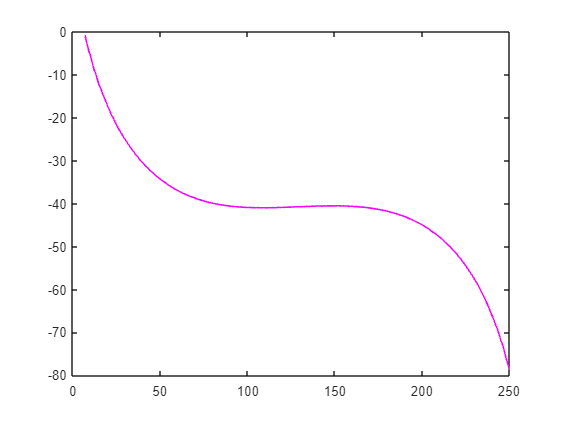


% 然后进行子载波域内的解卷绕
for t = 1:24
    for f = 2:241
        phase_diff = newphase_Z(t, f) -newphase_Z(t, f-1);

        % 如果相位差超过pi，进行解卷绕
        if phase_diff > pi
            while(abs(phase_diff)>pi)
                newphase_Z(t, f) = newphase_Z(t, f) - 2 * pi;
                phase_diff = newphase_Z(t, f) -newphase_Z(t, f-1);
            end
        end
        if phase_diff<-pi
           while(abs(phase_diff)>pi) 
                newphase_Z(t, f) = newphase_Z(t, f) + 2 * pi;
                phase_diff = newphase_Z(t, f) -newphase_Z(t, f-1);
           end
        end
    end
end
% 保存解卷绕后的数据
unwrappedCSI = newphase_Z;

c=cool(24);
for i = 1:24
figure(4);
plot(matrix,newphase_Z(i,:),'color', c(i,:),'DisplayName',strcat('第',num2str(i),'条天线'),'Linewidth',1);
hold on;
end